Reto 1: Parte 2

Profundización II: Electromedicina

Restauración de imágenes de leucocitos de un canino.

Leandro Ramos - 219160260

Brandon Rosero - 219160289

Inicio del código

clear; close all; clc

Obtención de la imágen

I=imread("S2_1.bmp");

Se extrae la capa roja

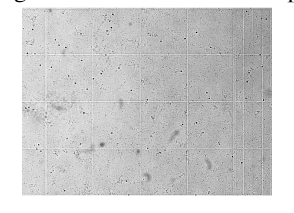

I=I(:,:,1);
imshow(I,[])
title('Imagen obtenida del microscopio','fontsize',14,'interpreter','latex');

Se aplica transformada de Fourier a la capa roja

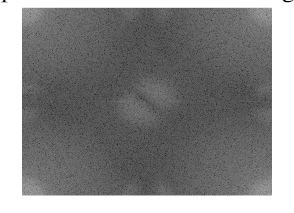

If=(fft2(I));
If1=(fftshift(If));
imshow(real(log(1+(If))),[])
title('Espectro de Fourier de la imagen','fontsize',14,'interpreter','latex')

Creación del filtro Notch

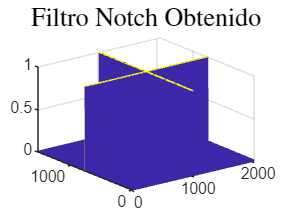

[P , Q]=size(If); %p filas q columbas
D=zeros(P,Q); %crear la matriz del mismo tamaño que la imágen
Do=1; %humbral de frecuencia
p2 = round(P/2);
q2 = round(Q/2);
D([p2-Do p2+Do],1:end) = 1 ;
D(1:end,[q2-Do q2+Do]) = 1;
H = D;
mesh(H)
title("Filtro Notch Obtenido",'fontsize',14,'interpreter','latex')

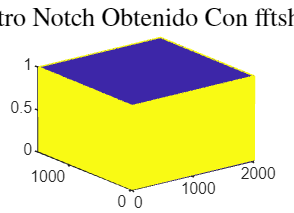


H1=fftshift(H);
mesh(H1)
title('Filtro Notch Obtenido Con fftshift','fontsize',14,'interpreter','latex')

Aplicación del filtro y eliminación de Interferencias

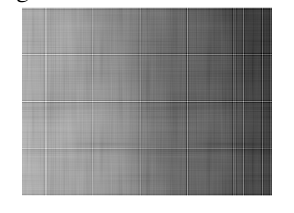

Bf=If.*H1;
%imshow(log(1+abs(Bf)),[])
I2=(ifft2(Bf)); 
I2=real(I2);
%I2 es el patrón de interferencia
Wa=(mean(double(I).*I2)-mean(double(I)).*mean(I2))/(mean(I2.*I2)-mean(I2).*mean(I2));
Ift=double(I)-Wa*I2;
Ift=real(Ift);
%Ift corresponde a la resta ponderada o la imágen sin interferencia.

imshow(I2,[])
title("Imagen de interferencia obtenida",'fontsize',14,'interpreter','latex')

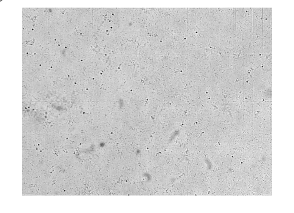

imshow(Ift,[]);
title("Imagen con la interferencia eliminada",'fontsize',14,'interpreter','latex')

Resta de vecidarios

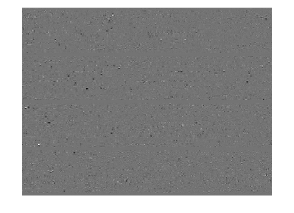

vecin = 4;

% Obtener el tamaño de las matrices
[f, c] = size(I);

% Inicializar la matriz de resultados
FNOpt = zeros(f, c);
clear Wa;
% Recorrer las regiones y realizar la resta
for i = 1:vecin:f
    for j = 1:vecin:c
        % Obtener la región actual
        Iseg = I(i:i+vecin-1, j:j+vecin-1);
        Iseg=double(Iseg);
        I2seg = I2(i:i+vecin-1, j:j+vecin-1);
        Wa=(mean(Iseg.*I2seg)-mean(Iseg).*mean(I2seg))/(mean(I2seg.*I2seg)-mean(I2seg).*mean(I2seg));
        % Realizar la resta de las regiones
        FNOpt(i:i+vecin-1, j:j+vecin-1) = Iseg - Wa.*I2seg;
    end
end

imshow(FNOpt,[]);

Aplicación del filtro Wiener en la imágen sin interferencias

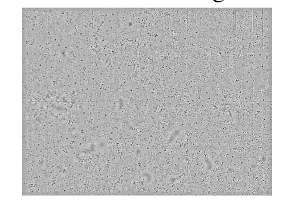

imagenfiltrada = wiener2(Ift, [70 70]); 
Iop=Ift-imagenfiltrada;
imshow(Iop,[]);
title("Fondo de la imagen",'fontsize',14,'interpreter','latex')

Wa=(mean(double(I).*I2)-mean(double(I)).*mean(I2))/(mean(I2.*I2)-mean(I2).*mean(I2));

Extracción del fondo de imágen

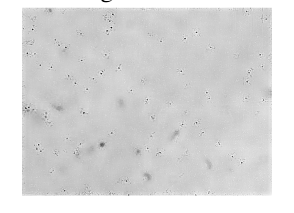

Iout=Ift-Wa*Iop;
imshow(Iout,[]);
title("Imagen obtenida",'fontsize',14,'interpreter','latex')